# Reading Weights from files

clc; clear;

N = 400;
baseDir = fullfile('Data', 'Scaled50', ['N' num2str(N)]);
folders = dir(baseDir);

% Filter only simulation subfolders
folders = folders([folders.isdir] & ~ismember({folders.name}, {'.', '..'}));
nFolders = length(folders);
nMemories = 100;
nSynapses = round(N*0.8) * 20;

% Preallocate 3D matrix: [memory × simulation × synapses]
w_all = nan(nMemories, nFolders, nSynapses);  % Use NaN for missing data

for f = 1:nFolders
    simFolder = folders(f).name;
    fprintf('Processing: %s\n', simFolder);

    for mem = 1:nMemories
        try
            filePath = fullfile(baseDir, simFolder, ...
                ['ttfs_mem' num2str(mem) '.mat']);
            S = load(filePath, 'net');

            net = S.net;
            mask = net.Adjacency_matrix(1:net.Ne, 1:net.Ne);
            w = net.w(1:net.Ne, 1:net.Ne);
            w = w(mask);  % flatten to 1D vector of connected weights

            w_all(mem, f, :) = w;
        catch
            warning('Skipped: %s (missing or corrupt)', filePath);
        end
    end
end

Processing: Apr_16_2025_16_42_42
Processing: Apr_16_2025_23_54_35
Processing: Apr_17_2025_07_34_17
Processing: Apr_17_2025_14_37_04
Processing: Apr_21_2025_11_43_49
Processing: Apr_21_2025_19_11_44
Processing: Apr_22_2025_03_05_51
Processing: Apr_22_2025_16_59_12
Processing: Apr_23_2025_00_13_35
Processing: Apr_23_2025_06_50_15


# Correlation matrix across all simulations

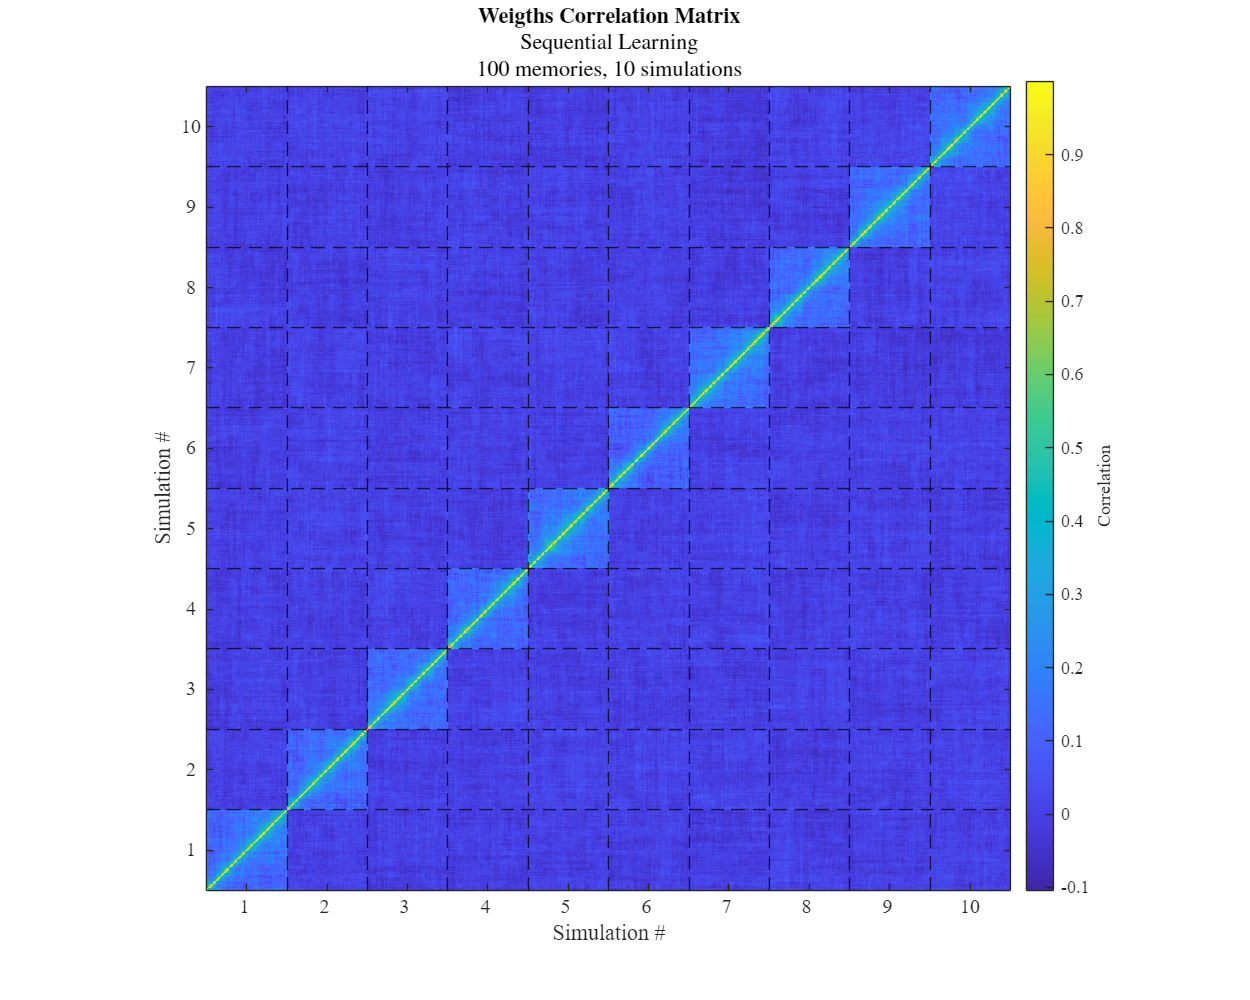

w_flatten = reshape(w_all, [], nSynapses);
MAT = 1- squareform(pdist(w_flatten, 'correlation'));

% Assumes w_all is [nMemories × nFolders × nSynapses]
nTotal = nMemories * nFolders;
tick_positions = (0:nFolders) * nMemories;

% Plot matrix
figure('Units', 'pixels', 'Position', [100, 100, 1000, 800]);
imagesc(MAT);
cb = colorbar(); cb.Label.String = "Correlation";
title({'\textbf{Weigths Correlation Matrix}', 'Sequential Learning', sprintf('%d memories, %d simulations', nMemories, nFolders)}, ...
    'Interpreter', 'latex');

% Set tick marks at sim boundaries
set(gca, 'XTick', tick_positions(2:end) - nMemories/2, ...
         'XTickLabel', 1:nFolders, ...
         'YTick', tick_positions(2:end) - nMemories/2, ...
         'YTickLabel', 1:nFolders);

xlabel('Simulation #', 'FontSize', 12, 'FontName', 'Times New Roman');
ylabel('Simulation #', 'FontSize', 12, 'FontName', 'Times New Roman');

% Draw simulation boundaries
hold on;
for t = tick_positions(2:end-1)
    xline(t + 0.5, 'k--', 'LineWidth', 0.5);
    yline(t + 0.5, 'k--', 'LineWidth', 0.5);
end

set(gca, 'FontSize', 12, 'FontName', 'Times New Roman', 'YDir', 'normal');
axis square;
print(fullfile("Results", "WeightsTracking","WeightCorrMatAllSimulation.png"), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "WeightsTracking","WeightCorrMatAllSimulation.pdf"), 'ContentType', 'vector', 'Resolution', 300)

# Computing withinsimulation and cross simulations corrs

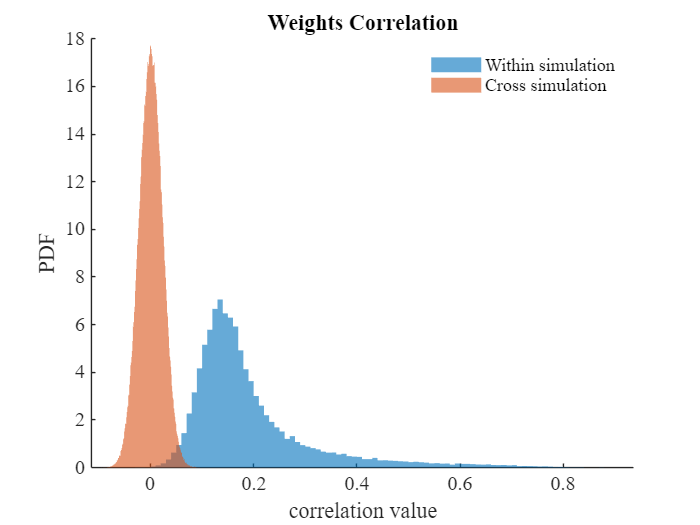

% Initialize
within_sims_data = [];
cross_sims_data = [];

% Sizes
nTotal = size(MAT, 1);  % total memories = nMemories * nFolders
nBlocks = nFolders;
blockSize = nMemories;

for s1 = 1:nBlocks
    idx1 = (s1-1)*blockSize + (1:blockSize);

    for s2 = 1:nBlocks
        idx2 = (s2-1)*blockSize + (1:blockSize);

        submat = MAT(idx1, idx2);

        if s1 == s2
            % Within-simulation (upper triangle only)
            within_sims_data = [within_sims_data; submat(triu(true(blockSize), 1))];
        else
            % Cross-simulation (all entries)
            cross_sims_data = [cross_sims_data; submat(:)];
        end
    end
end

figure; hold on;
histogram(within_sims_data, EdgeColor='none', Normalization='pdf', DisplayName='Within simulation')
histogram(cross_sims_data, EdgeColor='none', Normalization='pdf', DisplayName='Cross simulation')
legend('Box','off')
xlabel("correlation value")
ylabel("PDF")
title("Weights Correlation")
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

print(fullfile("Results", "WeightsTracking","InitialConditionEffect.png"), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "WeightsTracking","InitialConditionEffect.pdf"), 'ContentType', 'vector', 'Resolution', 300)

# Weights Correlation Matrix (Sequential Learning) for a single simulation

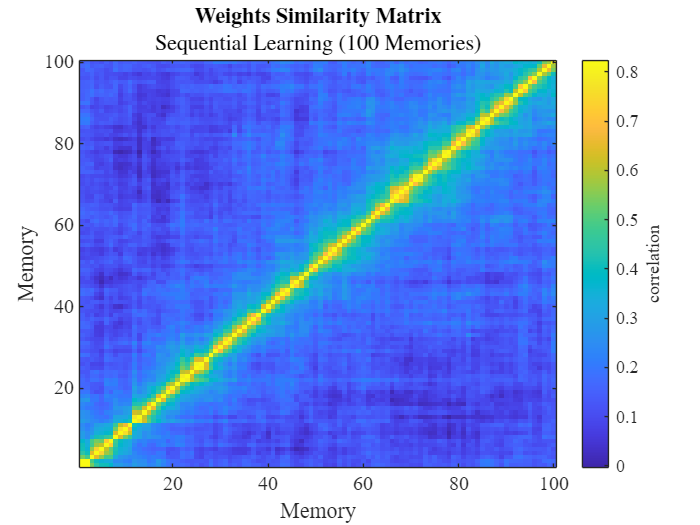


mat = 1 - squareform(pdist(squeeze(w_all(:, 1, :)), 'correlation'));

figure;
mat(logical(eye(size(mat)))) = max(triu(mat, 1), [], 'all');
imagesc(mat);
cb = colorbar();
cb.Label.String = 'correlation';
yticks(0:20:100)
xlabel('Memory');
ylabel('Memory');
title({'\textbf{Weights Similarity Matrix}', 'Sequential Learning (100 Memories)'}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman', 'Ydir', 'normal');

print(fullfile("Results", "WeightsTracking","WeigthCorrelationMat.png"), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "WeightsTracking","WeigthCorrelationMat.pdf"), 'ContentType', 'vector', 'Resolution', 300)

# Single Simulation Weight Similarity

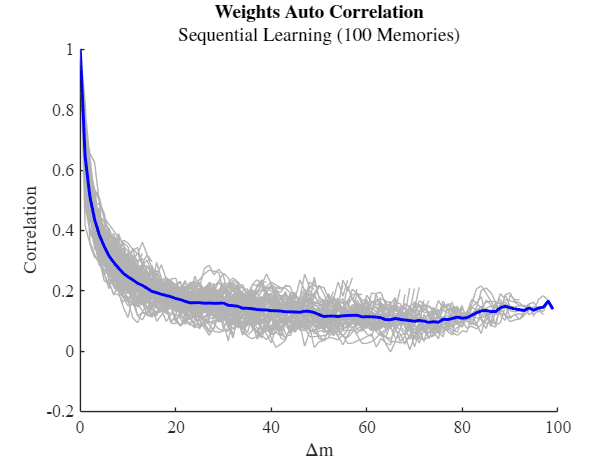


signal = nan(100, 199);

for m = 1:100
    signal(m, (100:199)-m+1) = mat(m, :);
end

% Compute mean and percentile-based confidence interval
mu = nanmean(signal, 1);                     % Mean across rows
low = prctile(signal, 2.5, 1);               % 2.5th percentile
high = prctile(signal, 97.5, 1);             % 97.5th percentile

x = (1:199) - 100;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure; hold on;
plot(repmat(x, 100, 1)', signal', 'Color', [0.7 0.7 0.7], 'LineWidth', 0.1);   % All trials

plot(x, mu, 'b', 'LineWidth', 2);  % Mean trace

xlim([0, 100]);
xlabel('$\Delta$m', 'Interpreter','latex');
ylabel('Correlation');
title({'\textbf{Weights Auto Correlation}', 'Sequential Learning (100 Memories)'}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

# Grand Average on independant simulations

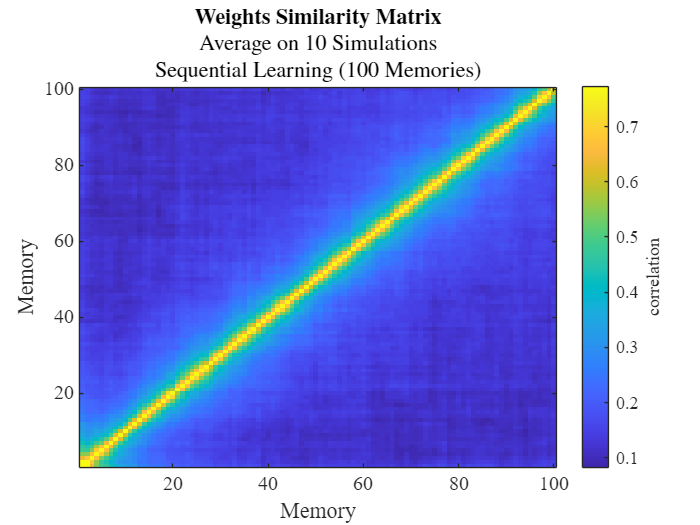


sim_mats = zeros(nMemories, nMemories, nFolders);  % [mem × mem × sim]

for f = 1:nFolders
    W = squeeze(w_all(:, f, :));  % [100 × 6400] for simulation f

    % Compute cosine similarity matrix
    D = pdist(W, 'correlation');            % 1 - cosine sim
    S = 1 - squareform(D);             % similarity matrix
    sim_mats(:, :, f) = S;
end

% Average across simulations
avg_mat = mean(sim_mats, 3, 'omitnan');

% Plot
figure;
avg_mat(logical(eye(size(avg_mat)))) = max(triu(avg_mat, 1), [], 'all');
imagesc(avg_mat);
cb = colorbar();
cb.Label.String = 'correlation';
xlabel('Memory');
ylabel('Memory');
title({'\textbf{Weights Similarity Matrix}', ...
        sprintf('Average on %d Simulations', nFolders), ...
       'Sequential Learning (100 Memories)'}, ...
       'Interpreter', 'latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman', 'YDir', 'normal');

# Grand Average on independant simulations

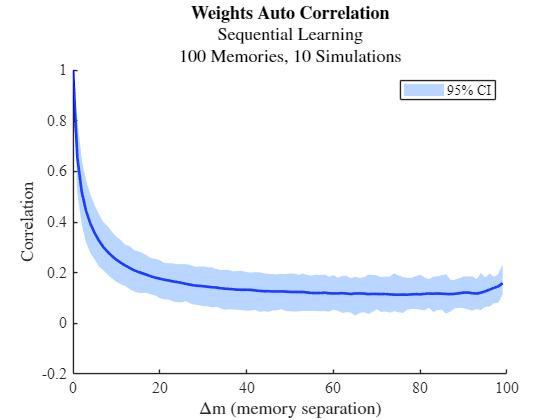

signal_all = nan(nFolders, nMemories, 199);

for j = 1:nFolders
    for m = 1:100
        signal_all(j, m, (100:199)-m+1) = sim_mats(m, :, j);
    end
end

% Assuming: signal_all [100 × 199 × nSimulations]
nSims = nFolders;
x = (1:199) - 100;

% Reshape into [trials × time] format
signal_reshaped = reshape(signal_all, [], 199);  % [nFolders * nMemories × 199]

mu = nanmean(signal_reshaped, 1);                % Mean across all trials
low = prctile(signal_reshaped, 2.5, 1);          % 2.5th percentile
high = prctile(signal_reshaped, 97.5, 1);        % 97.5th percentile


% Plot
figure; hold on;

plot(x, mu, 'b', 'LineWidth', 2, HandleVisibility='off');
fill([x, fliplr(x)], [high, fliplr(low)], ...
     [0.3 0.6 1], 'FaceAlpha', 0.4, 'EdgeColor', 'none', DisplayName='95% CI');

%%%%%%%%%%%% Adding baselines %%%%%%%%%%
% % Compute means and CIs
% mu_within = mean(within_sims_data);
% ci_within_high = prctile(within_sims_data, 97.5);
% ci_within_low = prctile(within_sims_data, 2.5);
% 
% mu_cross = mean(cross_sims_data);
% ci_cross_high = prctile(cross_sims_data, 97.5);
% ci_cross_low = prctile(cross_sims_data, 2.5);
% 
% % Horizontal shaded bands (95% CI)
% fill([-100 100 100 -100], ...
%      [ci_within_low ci_within_low ci_within_high ci_within_high], ...
%      [0.3 0.6 1], 'EdgeColor', 'none', 'FaceAlpha', 0.2);  % light blue
% 
% fill([-100 100 100 -100], ...
%      [ci_cross_low ci_cross_low ci_cross_high ci_cross_high], ...
%      [1 0.5 0.3], 'EdgeColor', 'none', 'FaceAlpha', 0.2);  % light orange

% Optional: dashed lines for means
% yline(mu_within, '--', 'Within Sim Mean', 'Color', [0.3 0.6 1], 'LineWidth', 1);
% yline(mu_cross, '--', 'Cross Sim Mean', 'Color', [1 0.5 0.3], 'LineWidth', 1);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

legend()

xlim([0, 100])
ylim([-0.2, 1])
xlabel('$\Delta$m (memory separation)', 'Interpreter','latex');
ylabel('Correlation');
title({'\textbf{Weights Auto Correlation}', 'Sequential Learning', sprintf('100 Memories,  %d Simulations', nFolders)}, 'Interpreter','latex');
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

print(fullfile("Results", "WeightsTracking","WeightsAutoCorrelation.png"), '-dpng', '-r300')
exportgraphics(gcf, fullfile("Results", "WeightsTracking","WeightsAutoCorrelation.pdf"), 'ContentType', 'vector', 'Resolution', 300)


save(fullfile("Data", "Scaled50", "N"+num2str(N), "weights_corr"), "signal_all")

## Power Law Fit!

% === Setup ===
x = (1:100)';  % domain
Y = signal_reshaped(:, 100:end)';  % shape: [100 x N]
nSamples = size(Y, 2);

% === Allocate Results ===
C0_all   = nan(1, nSamples);
A_all    = nan(1, nSamples);
b_all    = nan(1, nSamples);
Rsq_all  = nan(1, nSamples);

% === Define Fit Type ===
ftype = fittype('C0 + A*x.^(-b)', ...
    'independent', 'x', ...
    'coefficients', {'C0', 'A', 'b'});

% === Fit Loop ===
for i = 1:nSamples
    y = Y(:, i);
    valid_idx = isfinite(x) & isfinite(y);
    x_valid = x(valid_idx);
    y_valid = y(valid_idx);

    if numel(x_valid) < 30
        continue
    end

    try
        [fitresult, gof] = fit(x_valid, y_valid, ftype, ...
            'StartPoint', [0.05, 1, 0.7]);

        % Store parameters
        C0_all(i) = fitresult.C0;
        A_all(i)  = fitresult.A;
        b_all(i)  = fitresult.b;
        Rsq_all(i) = gof.rsquare;

    catch
        continue
    end
end

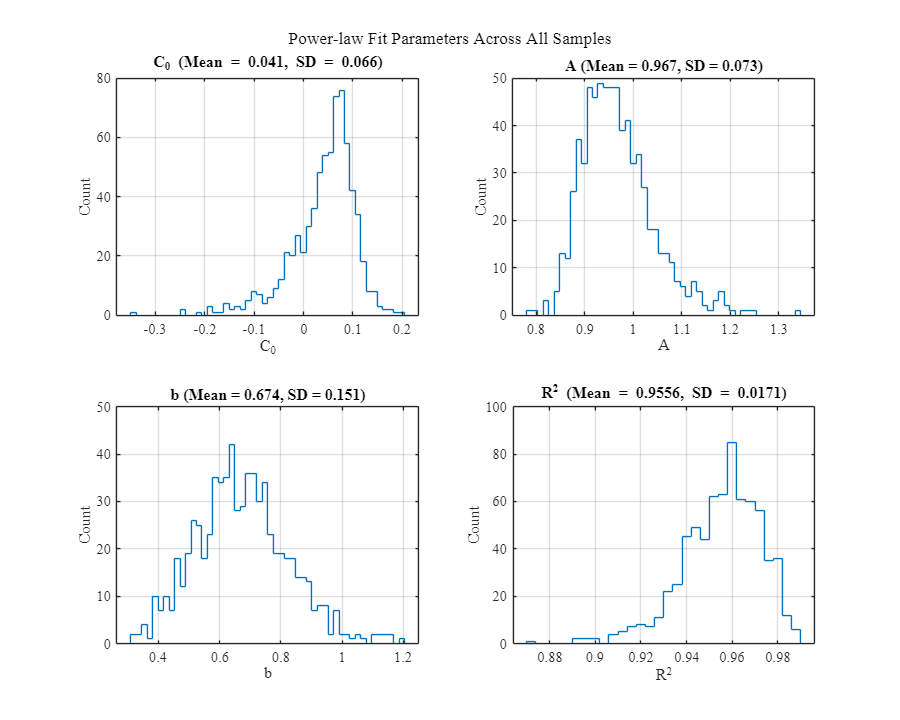


% === Compute Summary Statistics ===
mean_C0 = mean(C0_all, 'omitnan');
std_C0  = std(C0_all, 'omitnan');

mean_A = mean(A_all, 'omitnan');
std_A  = std(A_all, 'omitnan');

mean_b = mean(b_all, 'omitnan');
std_b  = std(b_all, 'omitnan');

mean_R2 = mean(Rsq_all, 'omitnan');
std_R2  = std(Rsq_all, 'omitnan');

% === Plot Histograms with Stats ===
figure('Name', 'Parameter Distributions', 'Position', [100 100 1000 800]);

subplot(2,2,1);
histogram(C0_all, 50, DisplayStyle="stairs"); grid on;
title(sprintf('C_0 (Mean = %.3f, SD = %.3f)', mean_C0, std_C0));
xlabel('C_0'); ylabel('Count'); 

subplot(2,2,2);
histogram(A_all, 50, DisplayStyle="stairs"); grid on;
title(sprintf('A (Mean = %.3f, SD = %.3f)', mean_A, std_A));
xlabel('A'); ylabel('Count'); 

subplot(2,2,3);
histogram(b_all, 50, DisplayStyle="stairs"); grid on;
title(sprintf('b (Mean = %.3f, SD = %.3f)', mean_b, std_b));
xlabel('b'); ylabel('Count');

subplot(2,2,4);
histogram(Rsq_all, 30, DisplayStyle="stairs"); grid on;
title(sprintf('R^2 (Mean = %.4f, SD = %.4f)', mean_R2, std_R2));
xlabel('R^2'); ylabel('Count');


sgtitle('Power-law Fit Parameters Across All Samples');

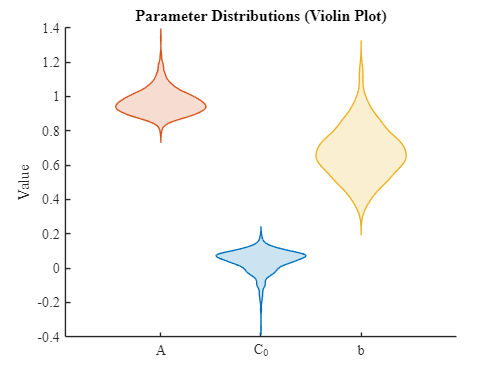

figure;

violinplot( categorical({'C_0', 'A', 'b'}), [C0_all(:), A_all(:), b_all(:)]);
title('Parameter Distributions (Violin Plot)');
ylabel('Value');

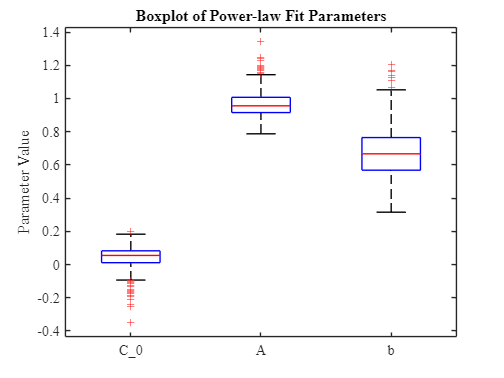

figure;
boxplot([C0_all(:), A_all(:), b_all(:)], 'Labels', {'C_0', 'A', 'b'});
ylabel('Parameter Value');
title('Boxplot of Power-law Fit Parameters');

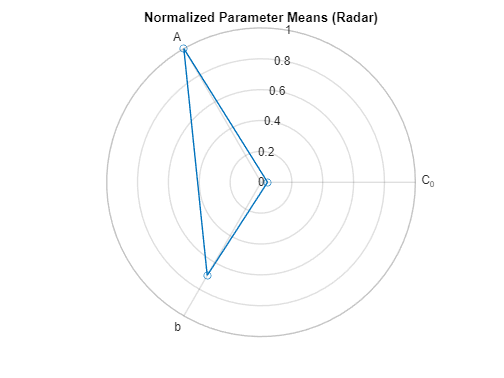

params_mean = [mean_C0, mean_A, mean_b];
params_std  = [std_C0, std_A, std_b];
labels = {'C_0', 'A', 'b'};

% Normalize for better spread
norm_means = params_mean ./ max(params_mean);

% Radar plot
figure;
polarplot([norm_means norm_means(1)], '-o');
thetalim([0 360]);
set(gca, 'ThetaTick', linspace(0, 360, numel(labels)+1), ...
         'ThetaTickLabel', [labels labels(1)]);
title('Normalized Parameter Means (Radar)');

# exponential Fit!

% === Setup ===
x = (1:100)';
Y = signal_reshaped(:, 100:end)';  % size: [100 x N]
nSamples = size(Y, 2);

% === Allocate Results ===
C0_all   = nan(1, nSamples);
A_all    = nan(1, nSamples);
b_all    = nan(1, nSamples);
Rsq_all  = nan(1, nSamples);

% === Define Exponential Fit Type ===
ftype = fittype('C0 + A*exp(-x/b)', ...
    'independent', 'x', ...
    'coefficients', {'C0', 'A', 'b'});

% === Fit Loop ===
for i = 1:nSamples
    y = Y(:, i);
    valid_idx = isfinite(x) & isfinite(y);
    x_valid = x(valid_idx);
    y_valid = y(valid_idx);

    if numel(x_valid) < 30
        continue
    end

    try
        [fitresult, gof] = fit(x_valid, y_valid, ftype, ...
            'StartPoint', [0.05, 1, 0.05]);  % Adjust if needed

        % Store parameters
        C0_all(i) = fitresult.C0;
        A_all(i)  = fitresult.A;
        b_all(i)  = fitresult.b;
        Rsq_all(i) = gof.rsquare;

    catch
        continue
    end
end

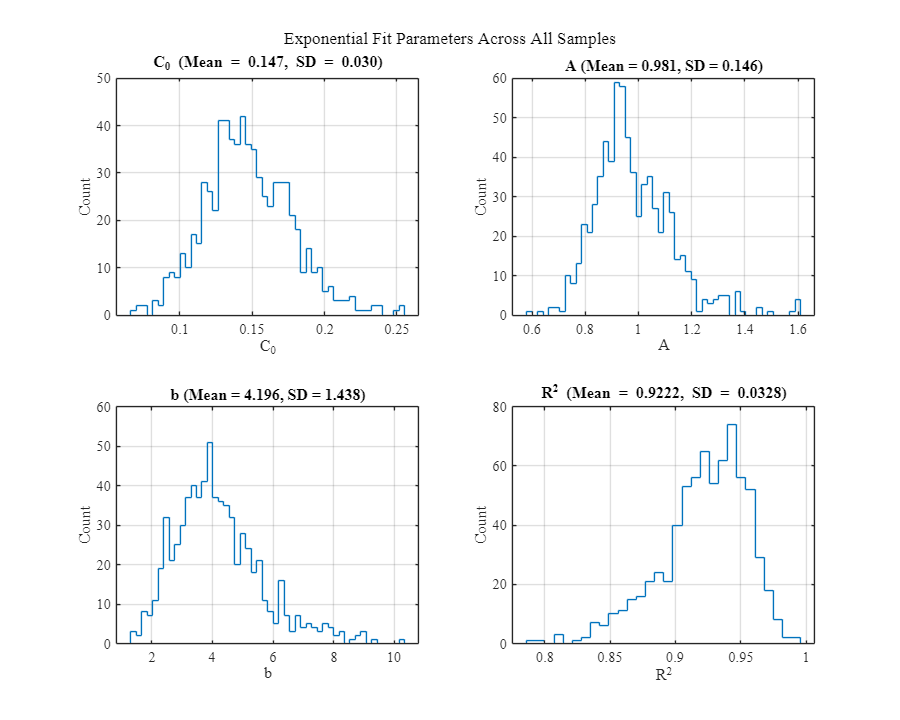


% === Compute Summary Statistics ===
mean_C0 = mean(C0_all, 'omitnan');    std_C0 = std(C0_all, 'omitnan');
mean_A  = mean(A_all, 'omitnan');     std_A  = std(A_all, 'omitnan');
mean_b  = mean(b_all, 'omitnan');     std_b  = std(b_all, 'omitnan');
mean_R2 = mean(Rsq_all, 'omitnan');   std_R2 = std(Rsq_all, 'omitnan');

% === Plot Histograms with Stats ===
figure('Name', 'Parameter Distributions', 'Position', [100 100 1000 800]);

subplot(2,2,1);
histogram(C0_all, 50, 'DisplayStyle', 'stairs'); grid on;
title(sprintf('C_0 (Mean = %.3f, SD = %.3f)', mean_C0, std_C0));
xlabel('C_0'); ylabel('Count'); 

subplot(2,2,2);
histogram(A_all, 50, 'DisplayStyle', 'stairs'); grid on;
title(sprintf('A (Mean = %.3f, SD = %.3f)', mean_A, std_A));
xlabel('A'); ylabel('Count'); 

subplot(2,2,3);
histogram(b_all, 50, 'DisplayStyle', 'stairs'); grid on;
title(sprintf('b (Mean = %.3f, SD = %.3f)', mean_b, std_b));
xlabel('b'); ylabel('Count');

subplot(2,2,4);
histogram(Rsq_all, 30, 'DisplayStyle', 'stairs'); grid on;
title(sprintf('R^2 (Mean = %.4f, SD = %.4f)', mean_R2, std_R2));
xlabel('R^2'); ylabel('Count');

sgtitle('Exponential Fit Parameters Across All Samples');

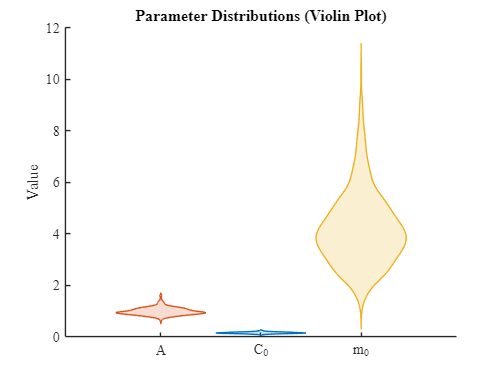


% === Violin Plot ===
figure;
violinplot(categorical({'C_0', 'A', 'm_0'}), [C0_all(:), A_all(:), b_all(:)]);
title('Parameter Distributions (Violin Plot)');
ylabel('Value');

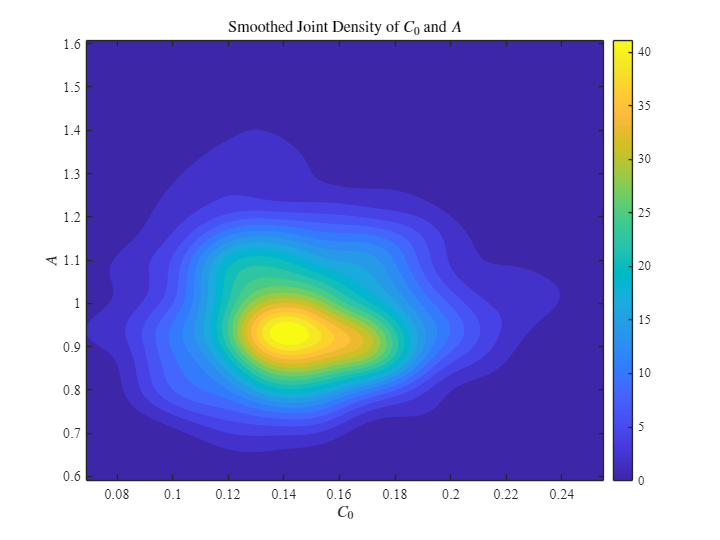

% Filter valid entries
valid_idx = isfinite(C0_all) & isfinite(A_all);
C0_valid = C0_all(valid_idx);
A_valid  = A_all(valid_idx);

% Create grid for KDE
xgrid = linspace(min(C0_valid), max(C0_valid), 100);
ygrid = linspace(min(A_valid), max(A_valid), 100);
[X, Y] = meshgrid(xgrid, ygrid);

% Evaluate kernel density
data = [C0_valid(:), A_valid(:)];
[f, ~] = ksdensity(data, [X(:), Y(:)]);

% Reshape and plot
f = reshape(f, size(X));

figure('Name', 'Smoothed KDE: C_0 vs A', 'Position', [100 100 800 600]);
contourf(X, Y, f, 20, 'LineColor', 'none');  % 20 levels
colorbar;
xlabel('$C_0$', 'Interpreter', 'latex');
ylabel('$A$', 'Interpreter', 'latex');
title('Smoothed Joint Density of $C_0$ and $A$', 'Interpreter', 'latex');

% Compute Pearson correlation
[r, pval] = corr(C0_valid(:), A_valid(:), 'Type', 'Pearson');

fprintf('Pearson correlation (r) = %.4f, p-value = %.4g\n', r, pval);

Pearson correlation (r) = 0.0292, p-value = 0.4367
